**1. ****Gauss-Seidel 방법의 이론적 배경**

**1) ****기본 원리**

- Gauss-Seidel 방법은 연립 방정식을 푸는 **반복적**(iterative) 방법 중 하나입니다.

- 이 방법은 **연립 일차 방정식**의 해를 점진적으로 근사하는 방식으로, 각 변수에 대해 **순차적으로 업데이트**하면서 수렴을 유도합니다.

**2) ****방정식의 재구성**

- 연립 방정식 $A \mathbf{x} = \mathbf{b}$를 Gauss-Seidel 방법에 맞게 다음과 같이 변형합니다. 각 변수는 다른 변수들의 이전 값을 사용하여 계산됩니다.

- 예를 들어, $x_1$을 풀기 위해 나머지 변수를 우변으로 넘기고, 그 변수를 계산한 후에 다시 대입합니다. 

$x_1 = \frac{b_1 - a_{12}x_2 - a_{13}x_3}{a_{11}}, \\ x_2 = \frac{b_2 - a_{21}x_1 - a_{23}x_3}{a_{22}}, \\ x_3 = \frac{b_3 - a_{31}x_1 - a_{32}x_2}{a_{33}}. \end{aligned}$�.�

**3) ****수렴 조건**

- Gauss-Seidel 방법은 **대각우월성**(diagonal dominance)이 있는 경우에 수렴을 보장합니다.

- 즉, 행렬의 대각 요소가 다른 행의 요소들의 합보다 커야 합니다.

- 대각우월성 조건을 만족하지 않으면 수렴이 불안정해지거나 무한 반복될 수 있습니다.

**2. ****예제 문제의 Gauss-Seidel 방법 적용**

다음 연립방정식을 Gauss-Seidel 방법으로 풀어보겠습니다.


$$ 3x_1 - 0.1x_2 - 0.2x_3 = 7.85, \\ 0.1x_1 + 7x_2 - 0.3x_3 = -19.3, \\ 0.3x_1 - 0.2x_2 + 10x_3 = 71.4. $$


�**1) ****초기값 설정**

- 첫 번째로 $x_1$�, $x_2$, $x_3$�의 **초기값**을 0으로 설정합니다. 이는 임의로 선택한 값이며, 반복을 통해 수렴하는 값을 찾아갑니다. $x_1^{(0)} = 0, \quad x_2^{(0)} = 0, \quad x_3^{(0)} = 0$.

**2) ****반복 계산 과정**

**STEP 1: 첫 번째 반복**

각 변수에 대해 첫 번째 반복을 수행합니다.

- $x_1$**�**** 계산**:


$$x_1^{(1)} = \frac{7.85 + 0.1 \cdot 0 + 0.2 \cdot 0}{3} = 2.616667$$


- 여기서 $x_1$을 구할 때, $x_2
$�와 $x_3$�는 0으로 대입됩니다.

- $x_2
$** 계산**:


$$x_2^{(1)} = \frac{-19.3 - 0.1 \cdot 2.616667 + 0.3 \cdot 0}{7} = -2.794524$$


- 여기서는 $x_1$�의 값을 이전에 계산된 2.616667로 대입하여 $x_2$�를 계산합니다.

- $x_3$**�**** 계산**:


$$x_3^{(1)} = \frac{71.4 - 0.3 \cdot 2.616667 + 0.2 \cdot (-2.794524)}{10} = 7.005610$$


- 여기서는 이전에 계산된 $x_1$�과 $x_2$�의 값을 사용하여 $x_3$를 계산합니다.

**STEP 2: 두 번째 반복**

두 번째 반복에서 각 변수를 다시 계산합니다.

- $x_1$** 계산**:


$$x_1^{(2)} = \frac{7.85 + 0.1 \cdot (-2.794524) + 0.2 \cdot 7.005610}{3} = 2.990557$$


- 이번에는 $x_2$�와 $x_3$의 값을 첫 번째 반복에서 계산한 값을 사용합니다.

- $x_2$** 계산**: 


$$x_2^{(2)} = \frac{-19.3 - 0.1 \cdot 2.990557 + 0.3 \cdot 7.005610}{7} = -2.499625$$


- 마찬가지로 이전 반복에서 계산된 $x_1$�과 $x_3$�의 값을 사용합니다.

- $x_3$** 계산**:


$$x_3^{(2)} = \frac{71.4 - 0.3 \cdot 2.990557 + 0.2 \cdot (-2.499625)}{10} = 7.000291$$


**3. ****수렴 여부 확인**

- 반복을 진행할 때마다 각 변수의 값이 조금씩 달라지며, 이 값들의 변화량이 매우 작아질 때 수렴했다고 판단합니다.

- 수렴 기준은 주어진 수식에 따라 계산할 수 있습니다: 


$$|e^k| = \max \left| \frac{x_i^{(k)} - x_i^{(k-1)}}{x_i^{(k)}} \right| \times 100.$$


- 이 값이 원하는 수렴 허용 오차 $\epsilon $ 이하가 될 때 계산을 멈추고 결과를 출력합니다.

**4. ****결론**

- Gauss-Seidel 방법은 대각우월성을 만족하는 선형 방정식에서 매우 효율적입니다.

- 각 반복에서 계산한 값을 다음 계산에 바로 사용하므로 빠르게 수렴할 수 있으며, 계산 과정이 비교적 간단합니다.

- 하지만, 수렴하지 않는 경우도 있으므로 대각우월성 여부를 확인하는 것이 중요합니다.

수렴 완료: 4번째 반복
    3.0000
   -2.5000
    7.0000



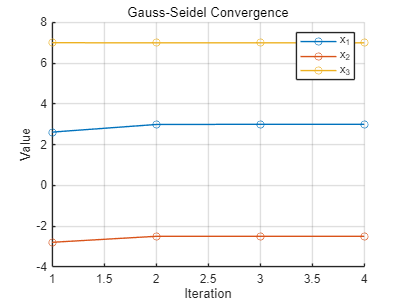

function gaussSeidel(A, b, tol)
    N = length(b);       % 계수 행렬의 크기
    x = zeros(N, 1);     % 초기값 (모든 변수를 0으로 설정)
    max_iter = 100;      % 최대 반복 횟수
    x_history = zeros(max_iter, N); % 시각화를 위한 기록 저장
    
    for count = 1:max_iter
        x_old = x;       % 이전 반복에서의 값을 저장
        for i = 1:N
            sigma = 0;   % sigma 값 초기화
            for j = 1:N
                if j ~= i
                    sigma = sigma + A(i, j) * x(j);
                end
            end
            x(i) = (b(i) - sigma) / A(i, i);
        end
        x_history(count, :) = x';  % 현재 값을 기록
        
        % 상대 오차 확인
        if max(abs((x - x_old) ./ x)) < tol
            disp(['수렴 완료: ' num2str(count) '번째 반복']);
            disp(x);
            x_history = x_history(1:count, :); % 사용한 반복 수만큼 저장
            break;
        end
    end
    
    % 시각화 부분
    figure;
    hold on;
    plot(1:size(x_history, 1), x_history(:, 1), '-o', 'DisplayName', 'x_1');
    plot(1:size(x_history, 1), x_history(:, 2), '-o', 'DisplayName', 'x_2');
    plot(1:size(x_history, 1), x_history(:, 3), '-o', 'DisplayName', 'x_3');
    xlabel('Iteration');
    ylabel('Value');
    title('Gauss-Seidel Convergence');
    legend('show');
    grid on;
    hold off;
    
    if count == max_iter
        disp('최대 반복 횟수 초과');
        disp(x);
    end
end


% 실행 부분
A = [3, -0.1, -0.2;
     0.1, 7, -0.3;
     0.3, -0.2, 10];    % 계수 행렬
b = [7.85; -19.3; 71.4]; % 상수 벡터
tol = 0.0005;           % 허용 오차

gaussSeidel(A, b, tol); % Gauss-Seidel 함수 실행

**1. ****수렴 조건 (17.2 수렴 판정)**

**고정점 반복법의 수렴 조건 (충분 조건)**

고정점 반복법에서 중요한 개념은 **수렴**입니다. 어떤 방정식을 반복적으로 계산할 때, 계산값이 특정 값에 수렴하는 것이 목표입니다. 수렴을 판단하기 위한 충분 조건은 다음과 같습니다.

- 주어진 조건에서 수렴 여부를 판단하는 방법은 방정식 내의 각 변수들의 **편미분**을 계산하여, 그 합이 1보다 작을 때 수렴한다고 보는 것입니다.

$E_{i+1} = g'(\zeta) E_i$�

- 이때, 반복을 통한 오차 $E_{i+1}$�가 이전 오차 $E_i$�의 함수 형태로 표현됩니다. 여기서 **편미분**이 사용되며, 각 편미분의 합이 1보다 작을 때, 결과값이 수렴할 가능성이 높다는 것을 의미합니다.

- 구체적인 수렴 조건은 다음과 같은 수식으로 표현됩니다:

$\left| \frac{\partial u}{\partial x} \right| + \left| \frac{\partial u}{\partial y} \right| < 1 \quad \text{그리고} \quad \left| \frac{\partial v}{\partial x} \right| + \left| \frac{\partial v}{\partial y} \right| < 1$�

- 이 조건은 편미분의 절대값이 1보다 작을 때 시스템이 수렴한다고 말하는 것인데, 이는 반복 계산에서 변수들의 값이 안정적으로 수렴할 수 있는지를 판단하는 중요한 기준입니다.

**대각선 지배성**

수렴 여부를 보장하는 또 하나의 중요한 조건은 **대각선 지배성**입니다. 대각선 지배성은 다음과 같이 정의됩니다:


$$|a_{ii}| > \sum_{i \neq j} |a_{ij}|$$


- 이 수식은 행렬의 **대각 성분** $a_{ii}$�가 그 행에 있는 나머지 성분 $a_{ij}$�들의 절대값의 합보다 큰 경우를 의미합니다. 즉, 각 행에서 대각 성분이 나머지 값들보다 더 큰 기여를 해야 시스템이 안정적으로 수렴할 가능성이 높다는 것을 의미합니다.

- 대각선 지배성은 수렴을 보장하는 중요한 수학적 조건으로, 특히 **Gauss-Seidel** 방법과 같은 반복법에서 수렴을 보장하는 핵심 요소입니다. 대각선 지배성이 만족되지 않으면 반복 계산 중에 값이 발산할 수 있으며, 그 결과 수렴하지 않는 현상이 발생할 수 있습니다.

**2. ****수렴성 개선 (17.3 수렴성 개선)**

**이완법 (Relaxation Method)**

이완법은 반복 계산에서 수렴성을 개선하거나 수렴 속도를 높이기 위해 사용하는 방법입니다. **이완 계수**를 사용해 현재 계산된 값과 이전 계산된 값의 **가중 평균**을 선택하는 방식입니다.

- **이완 계수** $\lambda $는 0에서 2 사이의 값입니다.

 
$$x_i^{(k)} = \lambda x_i^{(k)} + (1 - \lambda) x_i^{(k-1)}$$


- �이 수식은 현재 계산된 값 $x_i^{(k)}$�와 이전 값 $x_i^{(k-1)}$�를 **가중 평균**으로 결합하여 새로운 값을 만듭니다. $\lambda $ 값에 따라 새로운 값에 대한 비중이 결정되며, 이는 수렴 속도나 안정성에 영향을 미칩니다.

**하이 이완법 (Under-Relaxation, **$0 \leq \lambda \leq 1$**)**

- **하이 이완법**은 이완 계수 $\lambda $가 0과 1 사이일 때 적용됩니다.

- 이 방법은 주로 **수렴이 잘 되지 않는 시스템**에서 사용됩니다. 즉, 수렴성이 떨어지는 시스템에서 수렴 가능성을 높이기 위해 사용됩니다.

- $\lambda $ 값이 작을수록 이전 값 $x_i^{(k-1)}$�의 영향을 더 많이 반영하므로, 계산 값이 급격히 변하는 것을 방지하고 진동(damping)을 줄이는 효과가 있습니다. 이를 통해 반복 계산 과정이 보다 안정적으로 이루어지며, 수렴 가능성을 높일 수 있습니다.

- 결과적으로, 하이 이완법은 시스템의 수렴성을 향상시키며, 반복 계산에서 변동 폭을 줄여 **수렴 속도**를 향상시킬 수 있습니다.

**상 이완법 (Over-Relaxation, **$1 \leq \lambda \leq 2$**)**

- **상 이완법**은 $\lambda $ 값이 1과 2 사이일 때 적용됩니다.

- 상 이완법은 이미 **수렴하고 있는 시스템의 수렴 속도를 가속화**하는 데 사용됩니다.

- $\lambda $ 값이 1보다 크면, 현재 계산된 값 $x_i^{(k)}$�가 이전 값보다 더 큰 영향을 주게 되므로, 더 빠르게 수렴할 수 있습니다. 그러나 $\lambda $ 값이 너무 크면 안정성이 떨어질 수 있으므로, 적절한 값을 선택하는 것이 중요합니다.

- 이완 계수 $\lambda $는 시스템마다 최적의 값이 다를 수 있으며, 보통 경험적으로 선택됩니다.

**수렴성 개선을 위한 추가 고려 사항**

- **대각선 지배성 확인**: 이완법을 사용하더라도, 대각선 지배성이 중요한 수렴 조건입니다. 대각선 지배성이 만족되지 않으면 이완법을 사용해도 수렴이 보장되지 않을 수 있습니다.

- **반올림 오차와 수렴성**: 수렴성을 높이기 위해서는 **반올림 오차**와 같은 계산상의 오류도 고려해야 합니다. 반복 계산에서 발생할 수 있는 오차를 최소화하기 위한 계산 방법을 선택하는 것이 중요합니다.

- **희소행렬 및 대각행렬**: 대부분의 요소가 0인 **희소행렬**이나 대각선이 우세한 **대각행렬**에서는 이완법을 사용하면 **수렴 속도**를 크게 향상시킬 수 있습니다. 이러한 유형의 행렬에서는 이완법이 반복 계산의 효율성을 극대화할 수 있는 방법입니다.

**결론**

**Gauss-Seidel 방법**의 수렴 여부는 **대각선 지배성**과 같은 수학적 조건을 만족하는지에 따라 달라집니다. 대각선 지배성이 보장되는 경우, 반복 계산을 통해 해가 점진적으로 수렴하게 됩니다.

하지만, 수렴 속도를 높이거나 수렴성을 개선하기 위해 이완법(relaxation method)을 사용할 수 있습니다. 이완 계수 $\lambda $를 적절히 선택하면, 수렴이 잘 되지 않는 시스템에서 수렴성을 높이거나, 수렴 속도를 가속화할 수 있습니다.

- **하이 이완법**은 $0 \leq \lambda \leq 1$의 범위에서 적용되며, 수렴성이 떨어지는 시스템에서 안정성을 개선합니다.

- **상 이완법**은 $1 \leq \lambda \leq 2$의 범위에서 적용되며, 이미 수렴하고 있는 시스템의 수렴 속도를 가속화하는 데 사용됩니다.

이완 계수의 선택은 주로 **경험적**으로 이루어지며, 시스템의 특성에 맞는 적절한 값을 찾는 것이 중요합니다.